## Jubair Bin Masud

## 220021133

## Lab 6 Assignment

## 09 - 08 - 25

### Exc - 01

draw_Z(5)

ans =      1     1     1     1     1
     0     0     0     1     0
     0     0     1     0     0
     0     1     0     0     0
     1     1     1     1     1


draw_Z(3)

ans =      1     1     1
     0     1     0
     1     1     1


y = ~draw_Z(100)

y = 100×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1  

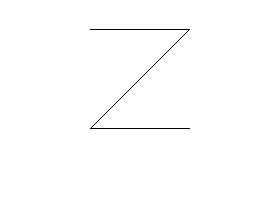

imshow(y)

### Exc - 02

repeat_elem(3)

ans =      1     2     2     3     3     3


repeat_elem(5)

ans =      1     2     2     3     3     3     4     4     4     4     5     5     5     5     5


repeat_elem(1)

ans = 1

### Exc - 03

Goldbach(10)

ans =      3     7


Goldbach(500000)

ans =           31      499969


Goldbach(2)

Error using eee_4416_ass_6>Goldbach
Numbers below or equal to 2 and odd numbers don't satisfy the conjecture.

Goldbach(101)

### Exc - 04

arith_op(20, 10,'sub')

ans = 10

arith_op(5, 10,'div')

ans = 0.5000

arith_op(22, 10)

ans = 2

arith_op(22)

Not enough input arguments.

Error in eee_4416_ass_6>arith_op (line 91)
    result = mod(a, b);

### Exc - 05

diag_dominant([5 0; 1, 5])

ans = logical
   1


diag_dominant([5, 0, 0, 10; 1, 5, 5, 10; 2, 4, 4, 5; 3, 2, 2, 1])

ans = logical
   0


diag_dominant([-2, 2, 1; 1, 3, 2; 1, -2, 0])

ans = logical
   0


diag_dominant([-4, 2, 1; 1, 6, 2; 1, -2, 5],'strict')

ans = logical
   1


diag_dominant( [5, 0, 0; 1, 5, 2; 2, 4, 6] ,'strict')

ans = logical
   0


diag_dominant( [5, 0, 0; 1, 5, 2; 2, 4, 6] ,'weak')

ans = logical
   1


### Exc - 06

knight_moves([5,5])

ans =      7     6
     6     7
     4     7
     3     6
     3     4
     4     3
     6     3
     7     4


knight_moves([1,1])

ans =      3     2
     2     3


knight_moves([8,8])

ans =      6     7
     7     6


knight_moves([8,9])

Error using eee_4416_ass_6>knight_moves
Invalid position

### Exc - 07

repeat_elem_v2(3)

ans =      1     2     2     3     3     3


repeat_elem_v2(5,4)

ans =      4     4     4     4     5     5     5     5     5


repeat_elem_v2(1)

ans = 1

repeat_elem_v2(1,8)


ans =

     []



repeat_elem_v2(6,6)

ans =      6     6     6     6     6     6


function Z = draw_Z(n)       %%  ex  01

if n <= 2
    disp('n must be greater than 2.');
    return;
end

Z = zeros(n);

Z(1, :) = 1;
Z(n, :) = 1;

for i = 1:n
    Z(i, n - i + 1) = 1;
end


end


%%  ex  02
function res = repeat_elem(n)

res = [];
for i = 1:n
    for j = 1:i
        res = [res, i];
    end
end
end


%%  ex  03
function prime_set = Goldbach(n)

if n <= 2 || mod(n,2) == 1
    error("Numbers below or equal to 2 and odd numbers don't satisfy the conjecture.");
end


prime_set = [];
primes_list = primes(n);
len = length(primes_list);

for i = 1:len
    for j = i:len
        if primes_list(i) + primes_list(j) == n
            prime_set(end+1,:) = [primes_list(i), primes_list(j)];
        end
    end
end

prime_set = sort(prime_set(1,:));

end


%%  ex  04
function result = arith_op(a, b, op)
if nargin < 3
    result = mod(a, b);
else
    switch op
        case 'add'
            result = a + b;
        case 'sub'
            result = a - b;
        case 'mul'
            result = a * b;
        case 'div'
            result = a / b;
        otherwise
            result = mod(a, b);
    end
end
end


%%  ex  05
function isDominant = diag_dominant(A, dominance_type)
if nargin < 2
    dominance_type = 'weak';
end

[m, n] = size(A);
if m ~= n
    error('Matrix must be square');
end

isDominant = true;

for i = 1:n
    row = A(i,:);
    diag_element = abs(row(i));
    sum_others = sum(abs(row)) - diag_element;

    if strcmpi(dominance_type, 'strict')
        if diag_element <= sum_others
            isDominant = false;
            return;
        end
    elseif strcmpi(dominance_type, 'weak')
        if diag_element < sum_others
            isDominant = false;
            return;
        end
    end
end
end

%%  ex  06
function valid_moves = knight_moves(position)

if any(position <= 0) || any(position > 8) || numel(position) ~= 2
    error('Invalid position');
end

move_offsets = [ 2,  1;  1,  2; -1,  2; -2,  1;
    -2, -1; -1, -2;  1, -2;  2, -1];


new_positions = position + move_offsets;


is_valid = all(new_positions >= 1 & new_positions <= 8, 2);
valid_moves = new_positions(is_valid, :);
end

%%  ex  07
function res = repeat_elem_v2(n,s)

if nargin < 2
    s = 1;
end

res = [];
for i = s:n
    for j = 1:i
        res = [res, i];
    end
end
end